clc; clear all;
load('MC_Results.mat');

disp("###################################### NORMAL QUATERNION ######################################");

###################################### NORMAL QUATERNION ######################################


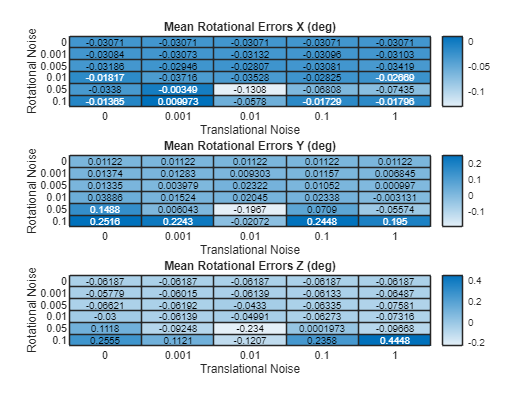

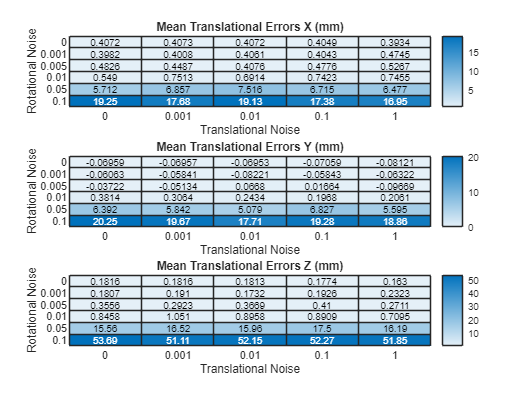

translationalNoisesCat = categorical(noiseLevelsNormal(:, 1));
rotationalNoisesCat = categorical(noiseLevelsNormal(:, 2));

uniqueTransNoise = unique(translationalNoisesCat);
uniqueRotNoise = unique(rotationalNoisesCat);

[error_x, error_tx] = calculos_errores(translationalNoisesCat, rotationalNoisesCat, rotationalErrorsNormal(:,1), translationalErrorsNormal(:,1), uniqueTransNoise, uniqueRotNoise);
[error_y, error_ty] = calculos_errores(translationalNoisesCat, rotationalNoisesCat, rotationalErrorsNormal(:,2), translationalErrorsNormal(:,2), uniqueTransNoise, uniqueRotNoise);
[error_z, error_tz] = calculos_errores(translationalNoisesCat, rotationalNoisesCat, rotationalErrorsNormal(:,3), translationalErrorsNormal(:,3), uniqueTransNoise, uniqueRotNoise);

[var_x, var_y, var_z] = calculos_varianza(translationalErrorsNormal, translationalNoisesCat, rotationalNoisesCat, uniqueTransNoise, uniqueRotNoise);
[var_tx, var_ty, var_tz] = calculos_varianza(rotationalErrorsNormal, translationalNoisesCat, rotationalNoisesCat, uniqueTransNoise, uniqueRotNoise);

plotting_errors(error_x, error_y, error_z, error_tx, error_ty, error_tz, uniqueTransNoise, uniqueRotNoise);

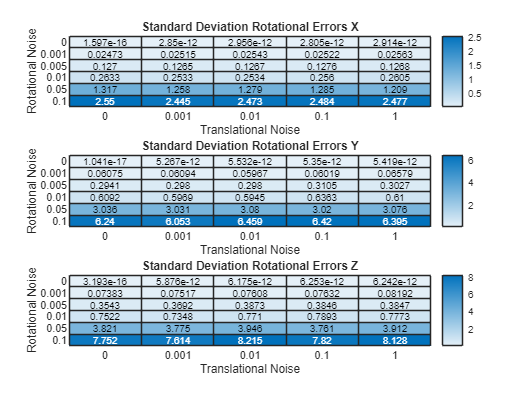

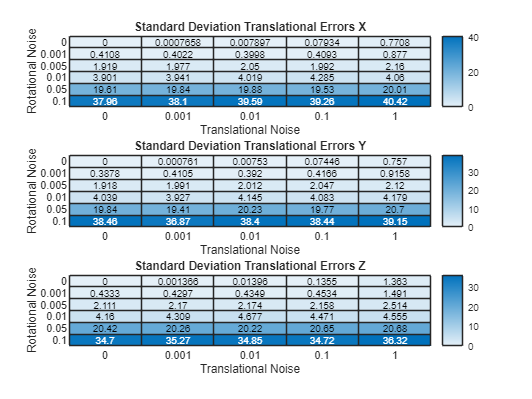

plotting_variance(var_x, var_y, var_z, var_tx, var_ty, var_tz, uniqueTransNoise, uniqueRotNoise);



disp("###################################### DUAL QUATERNION ######################################");

###################################### DUAL QUATERNION ######################################


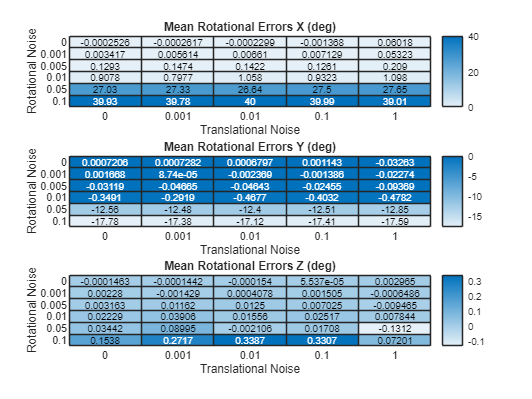

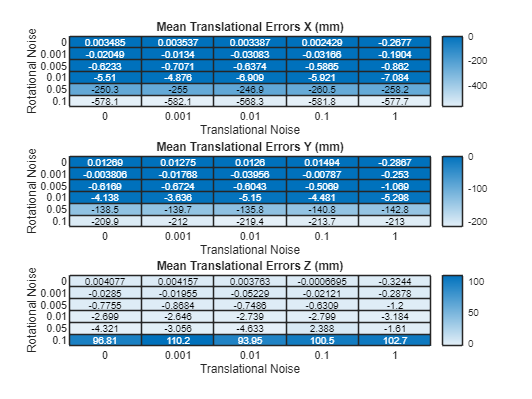

translationalNoisesCat = categorical(noiseLevelsDual(:, 1));
rotationalNoisesCat = categorical(noiseLevelsDual(:, 2));

uniqueTransNoise = unique(translationalNoisesCat);
uniqueRotNoise = unique(rotationalNoisesCat);

[error_x, error_tx] = calculos_errores(translationalNoisesCat, rotationalNoisesCat, rotationalErrorsDual(:,1), translationalErrorsDual(:,1), uniqueTransNoise, uniqueRotNoise);
[error_y, error_ty] = calculos_errores(translationalNoisesCat, rotationalNoisesCat, rotationalErrorsDual(:,2), translationalErrorsDual(:,2), uniqueTransNoise, uniqueRotNoise);
[error_z, error_tz] = calculos_errores(translationalNoisesCat, rotationalNoisesCat, rotationalErrorsDual(:,3), translationalErrorsDual(:,3), uniqueTransNoise, uniqueRotNoise);

[var_x, var_y, var_z] = calculos_varianza(translationalErrorsDual, translationalNoisesCat, rotationalNoisesCat, uniqueTransNoise, uniqueRotNoise);
[var_tx, var_ty, var_tz] = calculos_varianza(rotationalErrorsDual, translationalNoisesCat, rotationalNoisesCat, uniqueTransNoise, uniqueRotNoise);

plotting_errors(error_x, error_y, error_z, error_tx, error_ty, error_tz, uniqueTransNoise, uniqueRotNoise);

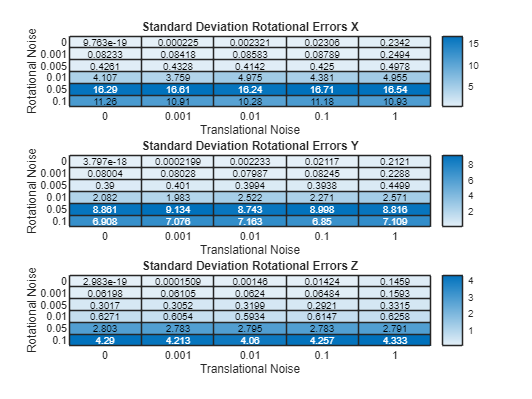

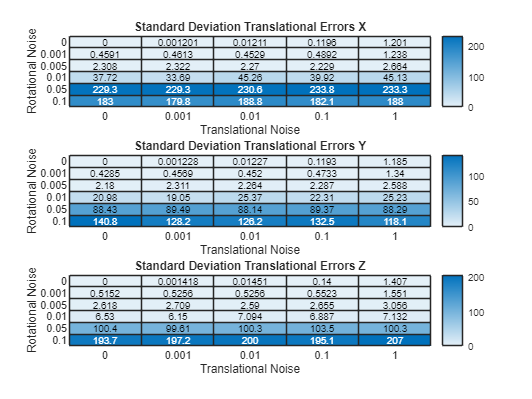

plotting_variance(var_x, var_y, var_z, var_tx, var_ty, var_tz, uniqueTransNoise, uniqueRotNoise);

function [trs, rot] = calculos_errores(translationalNoisesCat, rotationalNoisesCat, rotationalErrors, translationalErrors, uniqueTransNoise, uniqueRotNoise)
    
    rot = zeros(length(uniqueTransNoise), length(uniqueRotNoise));
    trs = zeros(length(uniqueTransNoise), length(uniqueRotNoise));
    
    for i = 1:length(uniqueTransNoise)
        for j = 1:length(uniqueRotNoise)
            idx = (translationalNoisesCat == uniqueTransNoise(i)) & (rotationalNoisesCat == uniqueRotNoise(j));
            rot(i, j) = mean(rotationalErrors(idx),"omitnan");
            trs(i, j) = mean(translationalErrors(idx),"omitnan");
        end
    end
end

function [var_x, var_y, var_z] = calculos_varianza(errors, translationalNoisesCat, rotationalNoisesCat, uniqueTransNoise, uniqueRotNoise)
    var_x = zeros(length(uniqueTransNoise), length(uniqueRotNoise));
    var_y = zeros(length(uniqueTransNoise), length(uniqueRotNoise));
    var_z = zeros(length(uniqueTransNoise), length(uniqueRotNoise));
    
    for i = 1:length(uniqueTransNoise)
        for j = 1:length(uniqueRotNoise)
            idx = (translationalNoisesCat == uniqueTransNoise(i)) & (rotationalNoisesCat == uniqueRotNoise(j));
    
            % Calculate and store covariance matrices
            covariance = cov([errors(idx,1), errors(idx,2), errors(idx,3)],"omitrows");
            var_x(i, j) = sqrt(covariance(1,1));
            var_y(i, j) = sqrt(covariance(2,2));
            var_z(i, j) = sqrt(covariance(3,3));
        end
    end
end

function plotting_errors(error_x, error_y, error_z, error_tx, error_ty, error_tz, uniqueTransNoise, uniqueRotNoise)
    figure;
    % Heat map for rotational errors
    subplot(3, 1, 1);
    heatmap(uniqueTransNoise, uniqueRotNoise, error_tx');
    title('Mean Rotational Errors X (deg)');
    xlabel('Translational Noise');
    ylabel('Rotational Noise');
    colorbar;
    
    subplot(3, 1, 2);
    heatmap(uniqueTransNoise, uniqueRotNoise, error_ty');
    title('Mean Rotational Errors Y (deg)');
    xlabel('Translational Noise');
    ylabel('Rotational Noise');
    colorbar;
    
    subplot(3, 1, 3);
    heatmap(uniqueTransNoise, uniqueRotNoise, error_tz');
    title('Mean Rotational Errors Z (deg)');
    xlabel('Translational Noise');
    ylabel('Rotational Noise');
    colorbar;

    figure;    
    % Heat map for translational errors
    subplot(3, 1, 1);
    heatmap(uniqueTransNoise, uniqueRotNoise, error_x');
    title('Mean Translational Errors X (mm)');
    xlabel('Translational Noise');
    ylabel('Rotational Noise');
    colorbar;
    
    subplot(3, 1, 2);
    heatmap(uniqueTransNoise, uniqueRotNoise, error_y');
    title('Mean Translational Errors Y (mm)');
    xlabel('Translational Noise');
    ylabel('Rotational Noise');
    colorbar;
    
    subplot(3, 1, 3);
    heatmap(uniqueTransNoise, uniqueRotNoise, error_z');
    title('Mean Translational Errors Z (mm)');
    xlabel('Translational Noise');
    ylabel('Rotational Noise');
    colorbar;
end

function plotting_variance(var_x, var_y, var_z, var_tx, var_ty, var_tz, uniqueTransNoise, uniqueRotNoise)
    figure;
    % Heat map for rotational errors
    subplot(3, 1, 1);
    heatmap(uniqueTransNoise, uniqueRotNoise, var_tx');
    title('Standard Deviation Rotational Errors X');
    xlabel('Translational Noise');
    ylabel('Rotational Noise');
    colorbar;
    
    subplot(3, 1, 2);
    heatmap(uniqueTransNoise, uniqueRotNoise, var_ty');
    title('Standard Deviation Rotational Errors Y');
    xlabel('Translational Noise');
    ylabel('Rotational Noise');
    colorbar;
    
    subplot(3, 1, 3);
    heatmap(uniqueTransNoise, uniqueRotNoise, var_tz');
    title('Standard Deviation Rotational Errors Z');
    xlabel('Translational Noise');
    ylabel('Rotational Noise');
    colorbar;
    
    figure;
    % Heat map for translational errors
    subplot(3, 1, 1);
    heatmap(uniqueTransNoise, uniqueRotNoise, var_x');
    title('Standard Deviation Translational Errors X');
    xlabel('Translational Noise');
    ylabel('Rotational Noise');
    colorbar;
    
    subplot(3, 1, 2);
    heatmap(uniqueTransNoise, uniqueRotNoise, var_y');
    title('Standard Deviation Translational Errors Y');
    xlabel('Translational Noise');
    ylabel('Rotational Noise');
    colorbar;
    
    subplot(3, 1, 3);
    heatmap(uniqueTransNoise, uniqueRotNoise, var_z');
    title('Standard Deviation Translational Errors Z');
    xlabel('Translational Noise');
    ylabel('Rotational Noise');
    colorbar;
end